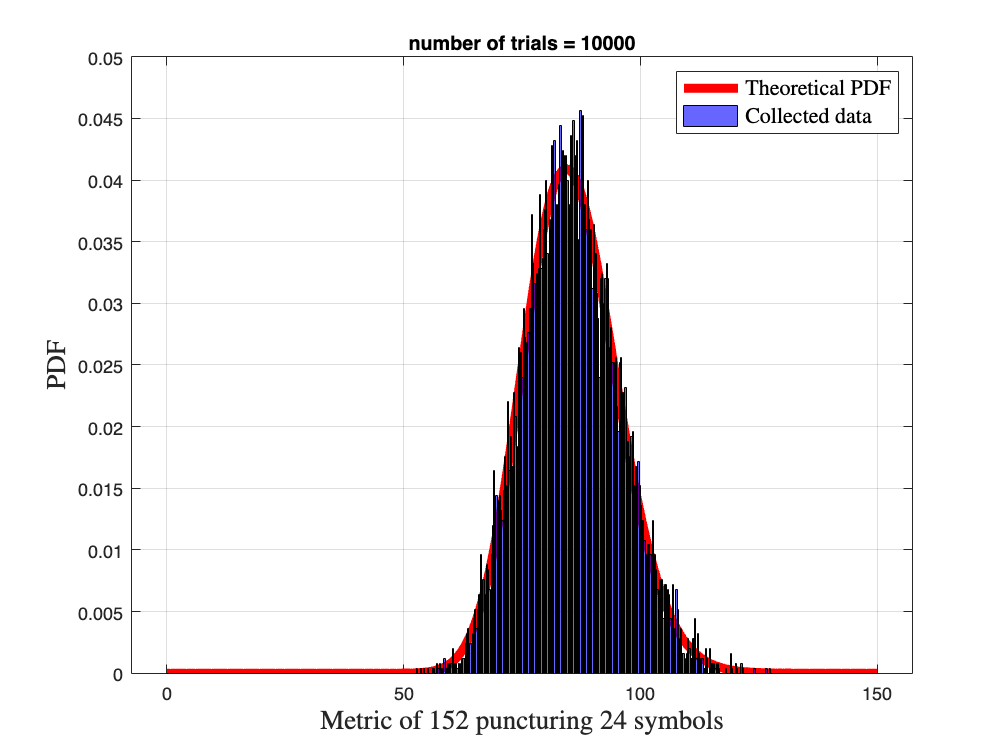

%% Rundundancy, systematic symbols theoretical PDF
% Comparing with collected data
close all;
clear;
clc;

unpunctured_152_metric = load('../output/unpunctured_152_metric.txt');
punctured_128_metric_plus24_incorrect = load('../output/punctured_128_metric_incorrect.txt');
punctured_128_metric_correct = load('../output/punctured_128_metric.txt');

displaying_metric = unpunctured_152_metric;

number_of_trials        = length(displaying_metric);
edges                   = 0:0.25:150;
number_of_elements      = 152;
SNR_dB                  = 2.5;
SNR                     = 10.^(SNR_dB./10);
noise_var               = 1./SNR;

% Ref
x_values    = linspace(0, 150, 400);
k           = number_of_elements ./ 2;
theta       = 2 .* noise_var;

gamma_pdf       = gampdf(x_values, k, theta);    %  symbols pdf

figure(1);
plot(x_values, gamma_pdf, 'r', 'LineWidth', 5, 'DisplayName', 'Theoretical PDF');
hold on;
% Res
histogram(displaying_metric, edges, 'Normalization', 'pdf', 'FaceColor', 'blue', 'EdgeColor', 'black', 'DisplayName', 'Collected data');

% plot
xlabel('Metric of 152 puncturing 24 symbols', 'FontSize', 15, 'Interpreter', 'latex');
ylabel('PDF', 'FontSize', 15, 'Interpreter', 'latex');
title(sprintf('number of trials = %d', number_of_trials));
legend('FontSize', 12, 'Interpreter', 'latex');
grid on;
hold off;

## Using gamma CDF to evaluate the minimum threshold $t$ such that $P(m^*_{r1}+m^*_{sys} > t) < 10^{-2}$


$$P(\text{min}(m^*_{r1}+m^*_{sys}, m^*_{sys}+m^*_{r2})  > t) = P(m^*_{r1}+m^*_{sys} > t) * P(m^*_{sys}+m^*_{r2} > t)$$


So a $t$ that guarantees $P(m^*_{r1}+m^*_{sys} > t) < 10^{-2}$ will also guarantee $P(m^*_{r1}+m^*_{sys} > t) * P(m^*_{sys}+m^*_{r2} > t) < 10^{-4}$, which means $P(\text{min}(m^*_{r1}+m^*_{sys}, m^*_{sys}+m^*_{r2})  > t) < 10^{-4}$.

Let $n = \text{number of symbols}$, $a = \frac{n}{2}$. $b = 2 \cdot \text{noise variance} = 2 \cdot \frac{1}{\text{SNR}}$.


$$\begin{array}{rcl}
\text{CDF} = F(x | a, b) 
&=& \frac{1}{b^a \Gamma(a)} \int_{0}^{x}t^{a-1}e^{\frac{-t}{b}}dt \\
&=& \frac{1}{(\frac{2}{\text{SNR}})^{\frac{n}{2}} \cdot \Gamma(\frac{n}{2})}  \int_{0}^{x}t^{\frac{n}{2}-1}e^{\frac{-t\cdot \text{SNR}}{2}}dt 
\end{array}$$


We want to find a $x_{thres}$ such that if $x > x_{thres}$, $F(x | \frac{n}{2}, \frac{2}{\text{SNR}}) \geq 1 - 0.01$

Thinking aloud here:

We could try to solve for x using the above: $0.99 = F(x | \frac{n}{2}, \frac{2}{\text{SNR}}) = \frac{1}{(\frac{2}{\text{SNR}})^{\frac{n}{2}} \cdot \Gamma(\frac{n}{2})}  \int_{0}^{x}t^{\frac{n}{2}-1}e^{\frac{-t\cdot \text{SNR}}{2}}dt $. But do we want to? 

Can we have the $x_{thres}$ computed ahead of time in real applications, and make it to be a look-up table?

threshold = 1e-2;
k_overall = (num_of_sys_elements + num_of_redun_elements) ./ 2;

Unrecognized function or variable 'num_of_sys_elements'.

gamma_redun_sys_cdf = gamcdf(x_values, k_overall, theta); % redundancy + systematic symbols cdf

thres_idx = length(gamma_redun_sys_cdf(gamma_redun_sys_cdf < 1 - threshold))+1;
x_thres = x_values(thres_idx)

% probability that min((m*r1+m*sys), (m*sys+m*r2)) > x_thres should be less
% than 10^-4
p = 2 .* (1 - gamcdf(x_thres, k_overall, theta)) .* gampdf(x_thres, k_overall, theta)

Let A be the event that $m^*_{r1}+m^*_{sys} > t$, and B be the event that $m^*_{sys}+m^*_{r2} > t$.

First question: A and B doesn't seem to be independent of each other, right?

Hence, $P(A) \cdot P(B) \neq P(A \cap B)$. However, we know that $P(A \cap B) = P(B)$

$\min(m^*_{r1}+m^*_{sys}, m^*_{r2}+m^*_{sys}) > t$, 